# Uncalibrated Stereo Image Rectification

This example shows how to use the [`estimateFundamentalMatrix`](docid:vision_ref#bsjglej), [`estimateStereoRectification`](docid:vision_ref#mw_5a3686f0-dadf-433b-8274-57a25d6b9cb1), and [`detectSURFFeatures`](docid:vision_ref#bs39_qf-1) functions to compute the rectification of two uncalibrated images, where the camera intrinsics are unknown.

Stereo image rectification projects images onto a common image plane in such a way that the corresponding points have the same row coordinates. This process is useful for stereo vision, because the 2-D stereo correspondence problem is reduced to a 1-D problem. As an example, stereo image rectification is often used as a preprocessing step for computing or creating anaglyph images. For more details, see the [Uncalibrated Stereo Image Rectifcation](docid:vision_ug#example-DepthEstimationFromStereoVideoExample) example.

## Step 1: Read Stereo Image Pair

Read in two color images of the same scene, which were taken from different positions. Then, convert them to grayscale. Colors are not required for the matching process.

I1 = imread("image1.jpg");
I2 = imread("image3.jpg");

% Convert to grayscale.
I1gray = im2gray(I1);
I2gray = im2gray(I2);

Display both images side by side. Then, display a color composite demonstrating the pixel-wise differences between the images.

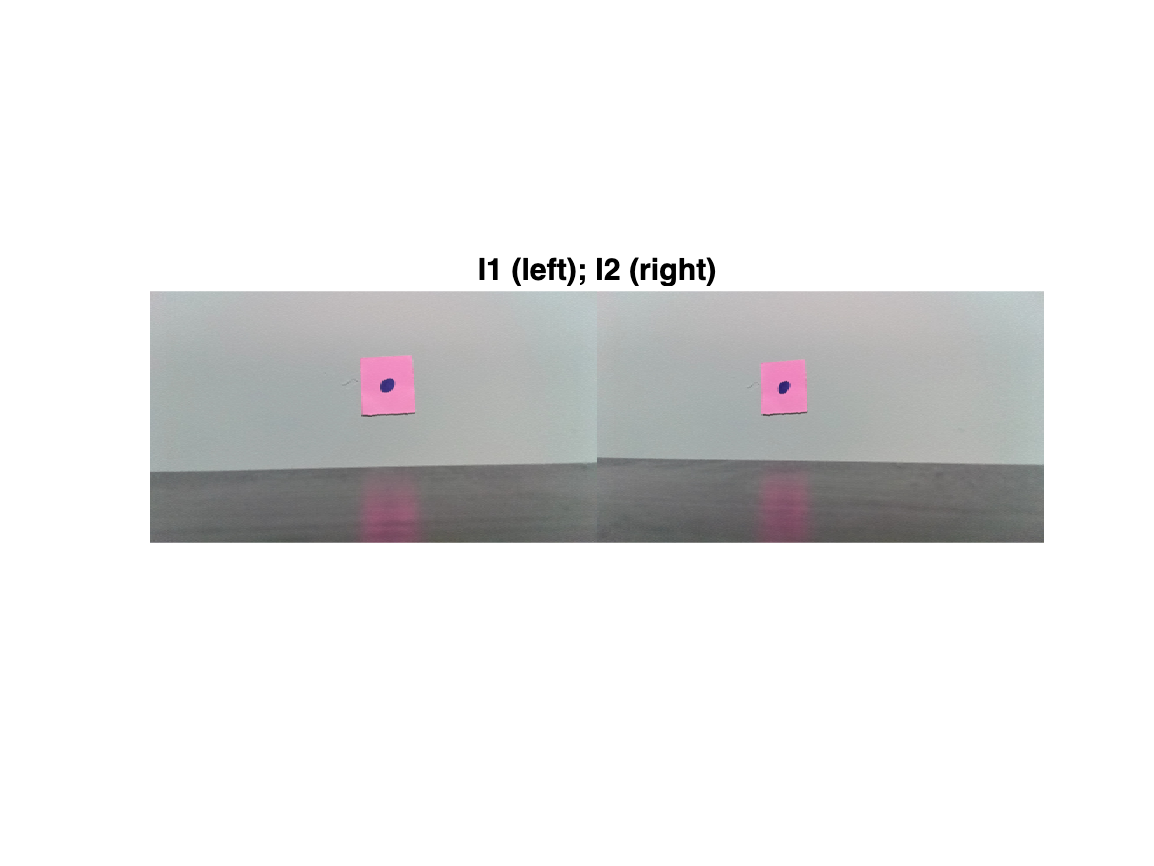

figure
imshowpair(I1,I2,"montage")
title("I1 (left); I2 (right)")

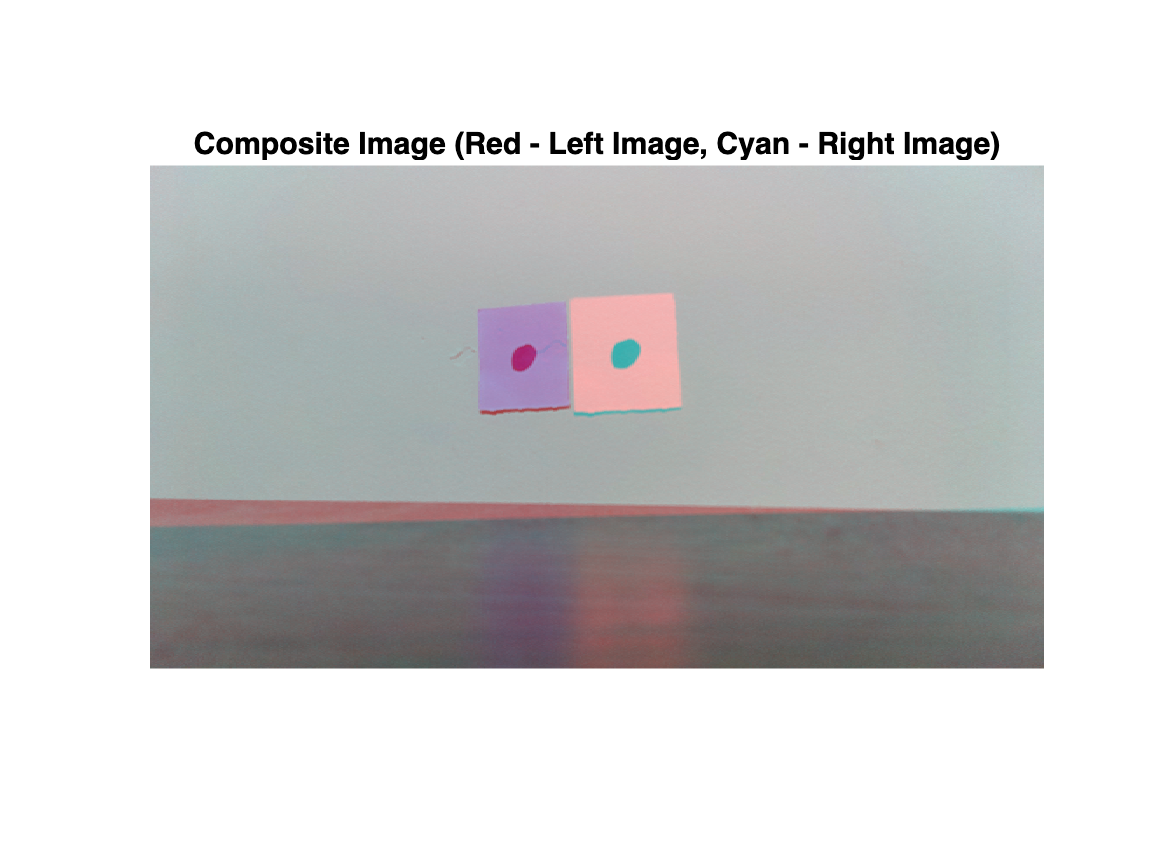

figure 
imshow(stereoAnaglyph(I1,I2))
title("Composite Image (Red - Left Image, Cyan - Right Image)")

There is an obvious offset between the images in orientation and position. The goal of rectification is to transform the images, aligning them such that corresponding points will appear on the same rows in both images.

## Step 2: Collect Interest Points from Each Image

The rectification process requires a set of point correspondences between the two images. To generate these correspondences, you will collect points of interest from both images, and then choose potential matches between them. Use `detectSURFFeatures` to find blob-like features in both images.

blobs1 = detectSURFFeatures(I1gray,MetricThreshold=100);
blobs2 = detectSURFFeatures(I2gray,MetricThreshold=100);

Visualize the location and scale of the thirty strongest SURF features in I1 and I2. Notice that not all of the detected features can be matched because they were either not detected in both images or because some of them were not present in one of the images due to camera motion.

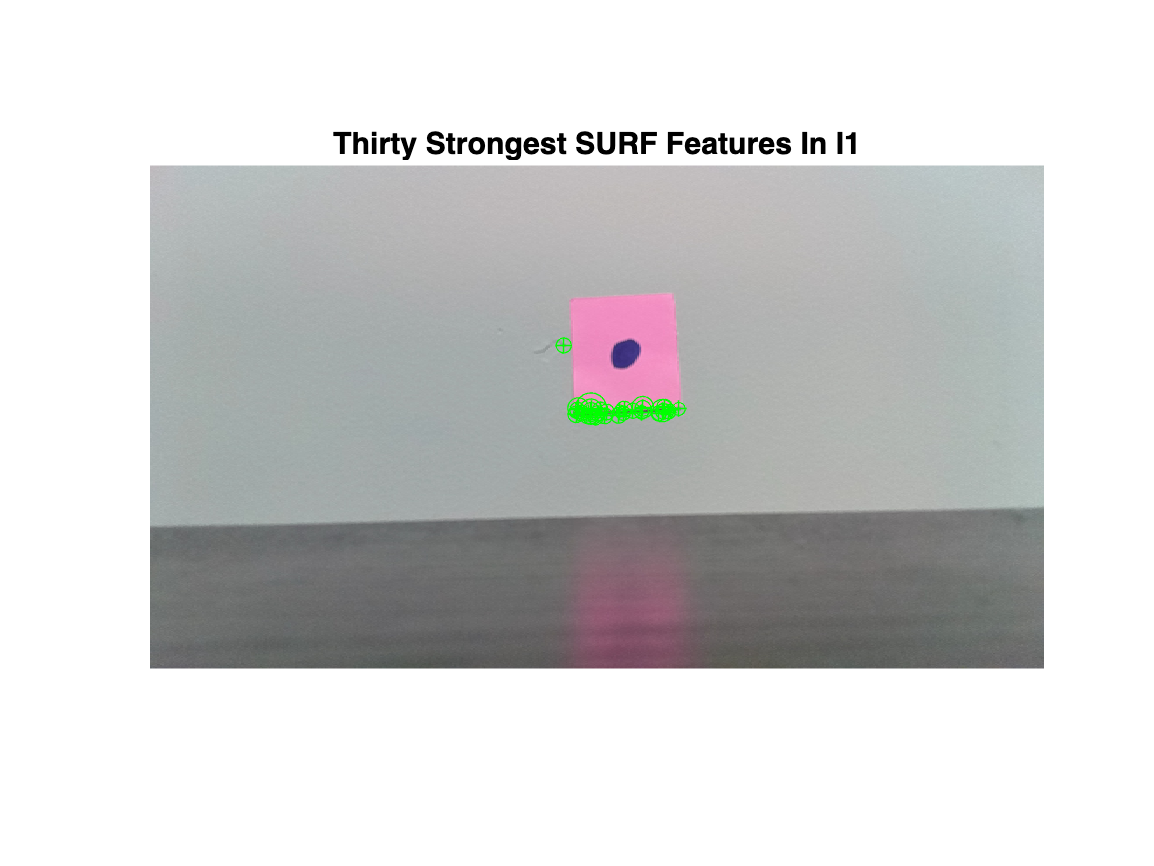

figure 
imshow(I1)
hold on
plot(selectStrongest(blobs1,30))
title("Thirty Strongest SURF Features In I1")

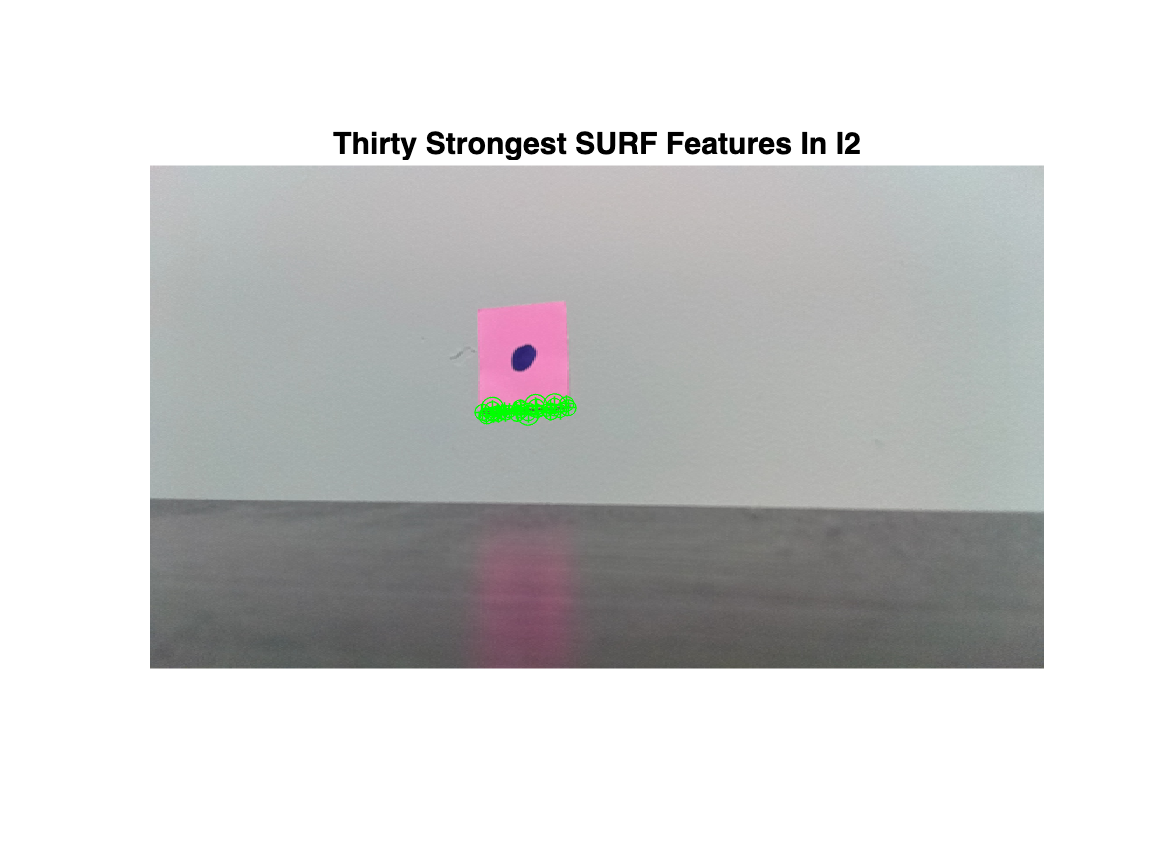


figure
imshow(I2)
hold on
plot(selectStrongest(blobs2,30))
title("Thirty Strongest SURF Features In I2")

## Step 3: Find Putative Point Correspondences

Use the `extractFeatures` and `matchFeatures` functions to find putative point correspondences. For each blob, compute the SURF feature vectors (descriptors).

[features1,validBlobs1] = extractFeatures(I1gray,blobs1);
[features2,validBlobs2] = extractFeatures(I2gray,blobs2);

Use the sum of absolute differences (SAD) metric to determine indices of matching features.

indexPairs = matchFeatures(features1,features2,Metric="SSD", ...
  MatchThreshold=5);

Retrieve locations of matched points for each image.

matchedPoints1 = validBlobs1(indexPairs(:,1),:);
matchedPoints2 = validBlobs2(indexPairs(:,2),:);

matchedPoints1

matchedPoints1 =   19x1 SURFPoints array with properties:

              Scale: [19x1 single]
    SignOfLaplacian: [19x1 int8]
        Orientation: [19x1 single]
           Location: [19x2 single]
             Metric: [19x1 single]
              Count: 19


matchedPoints2

matchedPoints2 =   19x1 SURFPoints array with properties:

              Scale: [19x1 single]
    SignOfLaplacian: [19x1 int8]
        Orientation: [19x1 single]
           Location: [19x2 single]
             Metric: [19x1 single]
              Count: 19


Show matching points on top of the composite image, which combines stereo images. Notice that most of the matches are correct, but there are still some outliers.

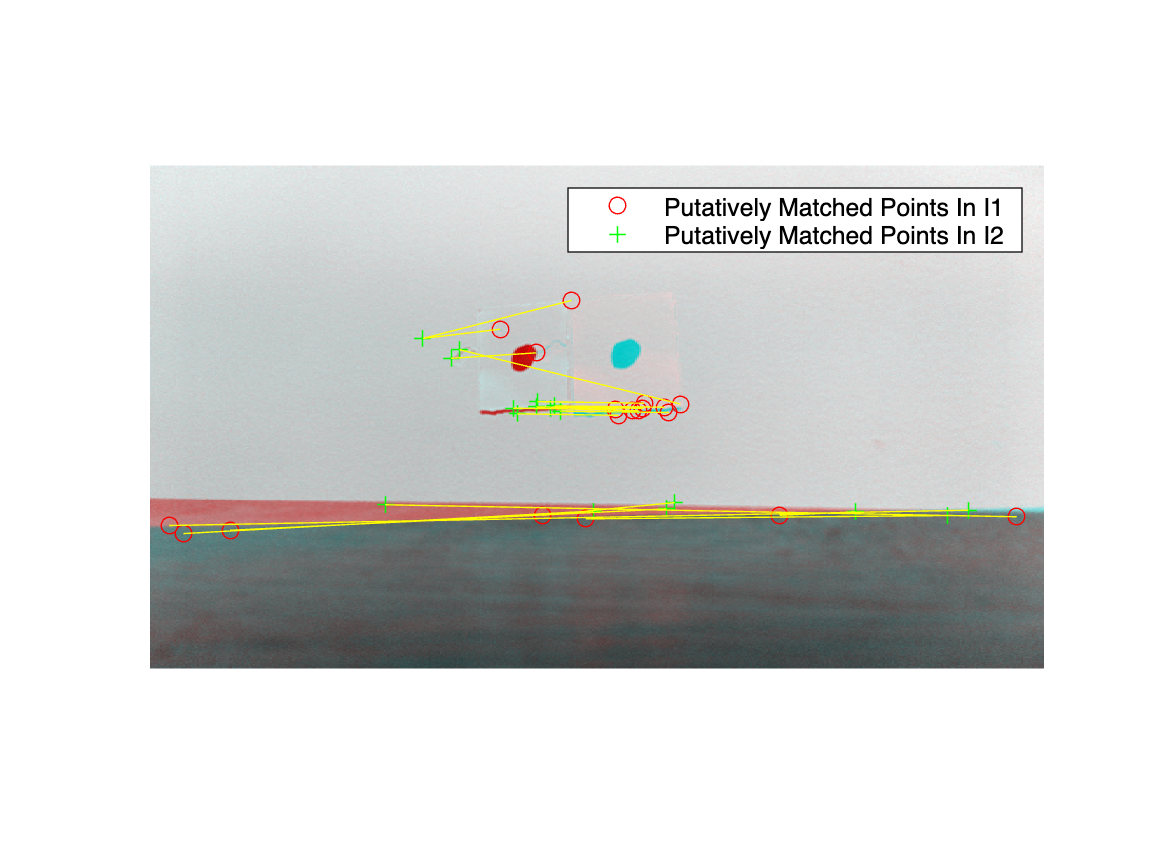

figure 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2)
legend("Putatively Matched Points In I1","Putatively Matched Points In I2")

## Step 4: Remove Outliers Using Epipolar Constraint

The correctly matched points must satisfy epipolar constraints. This means that a point must lie on the epipolar line determined by its corresponding point. You will use the `estimateFundamentalMatrix` function to compute the fundamental matrix and find the inliers that meet the epipolar constraint.

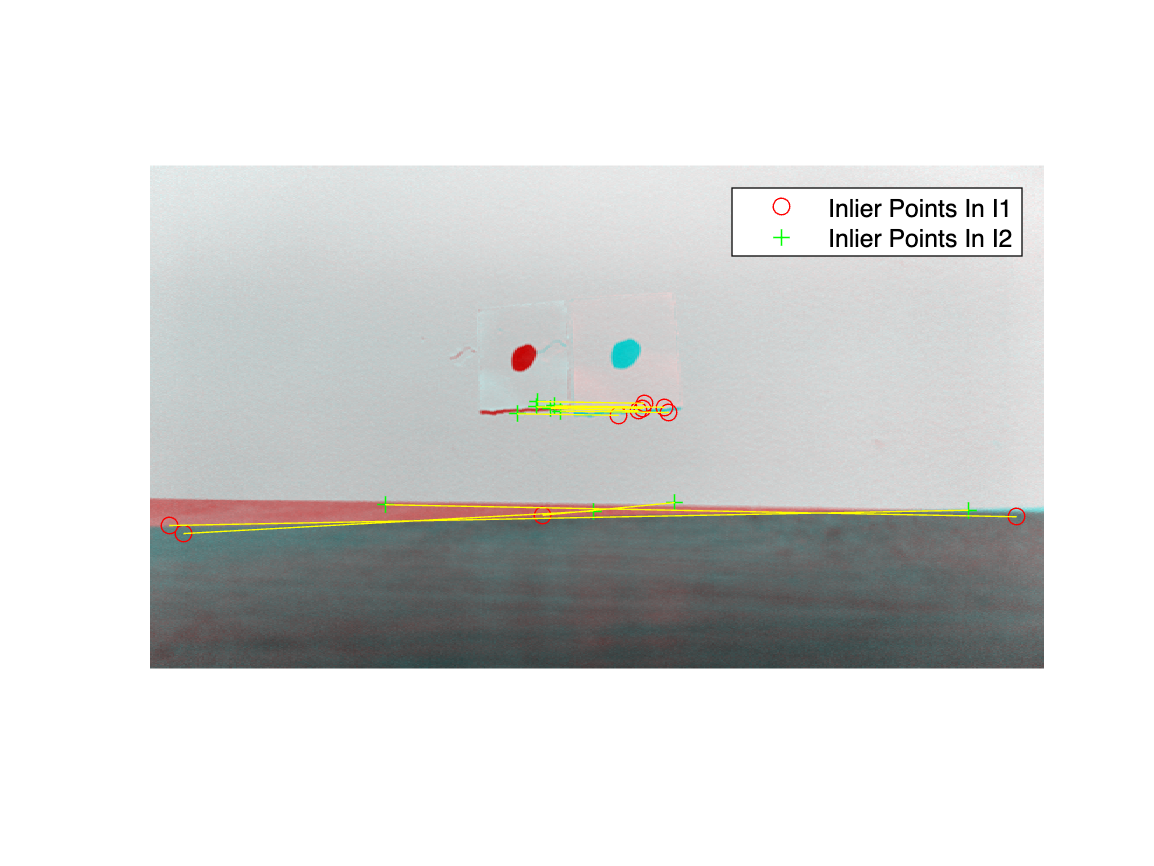

[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
  matchedPoints1,matchedPoints2,Method="RANSAC", ...
  NumTrials=200,DistanceThreshold=0.1,Confidence=99.99);
  


inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2)
legend("Inlier Points In I1","Inlier Points In I2")

## Step 5: Rectify Images

Use the `estimateStereoRectification` function to compute the rectification transformations. These can be used to transform the images, such that the corresponding points will appear on the same rows.

[tform1, tform2] = estimateStereoRectification(fMatrix, ...
  inlierPoints1.Location,inlierPoints2.Location,size(I2));

Rectify the stereo images, and display them as a stereo anaglyph. You can use red-cyan stereo glasses to see the 3D effect.

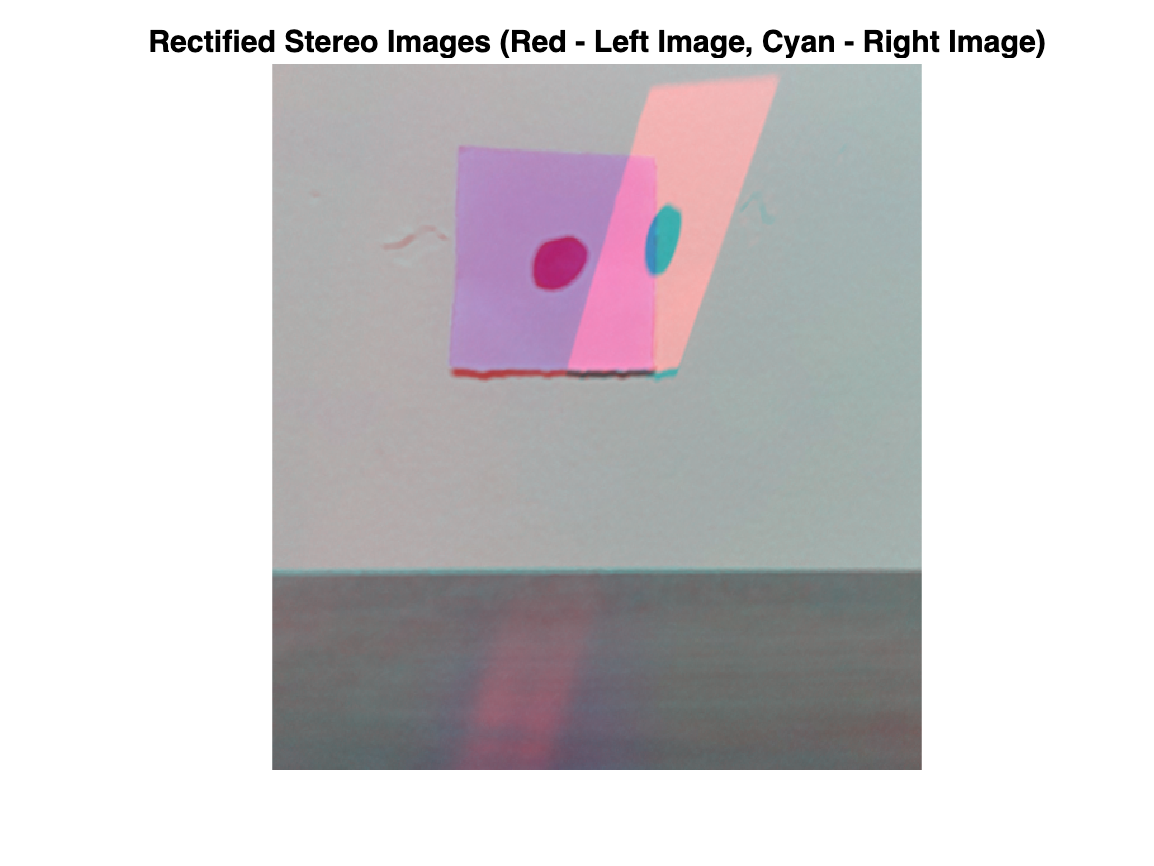

[I1Rect, I2Rect] = rectifyStereoImages(I1,I2,tform1,tform2);
figure
imshow(stereoAnaglyph(I1Rect,I2Rect))
title("Rectified Stereo Images (Red - Left Image, Cyan - Right Image)")

## Step 6: Detecting depth

This code furhter calculates the depth of the wall from the camera

% Convert rectified images to grayscale if they are not already
I1Gray = rgb2gray(I1Rect);
I2Gray = rgb2gray(I2Rect);

% Calculate the disparity map using the Semi-Global Matching algorithm
disparityRange = [350, 358];  % This should be adjusted based on the specific setup
disparityMap = disparitySGM(I1Gray, I2Gray, 'DisparityRange', disparityRange, 'UniquenessThreshold', 15);

% Known camera parameters
baselineMeters = 0.052;  % The distance between the two camera centers in meters
focalLengthPixels = 1495;  % The focal length of the cameras in pixels

% Convert disparity to depth in millimeters
disparityMap(disparityMap == 0) = 0.1;  % Small value to avoid division by zero
depthMap = (focalLengthPixels * baselineMeters) ./ disparityMap * 1000;  % Convert meters to millimeters

% Calculate depth at a specific point, e.g., the center of the image
centerX = size(I1Gray, 1) / 2;
centerY = size(I1Gray, 1) / 2;
depthAtCenter = depthMap(round(centerY), round(centerX));

% Optionally calculate average depth over a defined ROI, e.g., central square
roiSize = 100;  % Define the size of the ROI square
xRange = round(centerX - roiSize/2) : round(centerX + roiSize/2);
yRange = round(centerY - roiSize/2) : round(centerY + roiSize/2);
averageDepthROI = mean(depthMap(yRange, xRange), 'all', 'omitnan');

% Output the calculated depths
fprintf('Depth at the center of the image: %.2f mm\n', depthAtCenter);

Depth at the center of the image: 220.23 mm


fprintf('Average depth in the defined ROI: %.2f mm\n', averageDepthROI);

Average depth in the defined ROI: 220.36 mm


## References

[1] Trucco, E; Verri, A. "Introductory Techniques for 3-D Computer Vision." Prentice Hall, 1998.

[2] Hartley, R; Zisserman, A. "Multiple View Geometry in Computer Vision." Cambridge University Press, 2003.

[3] Hartley, R. "In Defense of the Eight-Point Algorithm." IEEE® Transactions on Pattern Analysis and Machine Intelligence, v.19 n.6, June 1997.

[4] Fischler, MA; Bolles, RC. "Random Sample Consensus: A Paradigm for Model Fitting with Applications to Image Analysis and Automated Cartography." Comm. Of the ACM 24, June 1981.

*Copyright 2004-2014 The MathWorks, Inc.*